## Load Data

% unzip('MerchData.zip');
% imds = imageDatastore('MerchData', ...
%     'IncludeSubfolders',true, ...
%     'LabelSource','foldernames'); 
% [imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);


DatasetPath = 'C:\Users\Home\Documents\data ML\Augmented images of classes';
imds = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
labelCount = countEachLabel(imds)

labelCount = 7×2 table
        Label         Count
    ______________    _____

    Black Chaff       1000 
    Healthy Leave     1000 
    Leaf Blotch       1000 
    Leaf Rust         1000 
    Powdery Mildew    1000 
    Smut              1000 
    Stripe rust       1000 



img = readimage(imds,1);
size(img)

ans =    224   224     3



numTrainPercent = .75;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainPercent,'randomize');

## Load Pretrained Network

net = resnet50;

analyzeNetwork(net)

net.Layers(1)

ans =   ImageInputLayer with properties:

                Name: 'input_1'
           InputSize: [224 224 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: [224×224×3 single]


inputSize = net.Layers(1).InputSize;

## Replace Final Layers

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1x2 Layer array with layers:

     1   'fc1000'                       Fully Connected         1000 fully connected layer
     2   'ClassificationLayer_fc1000'   Classification Output   crossentropyex with 'tench' and 999 other classes

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

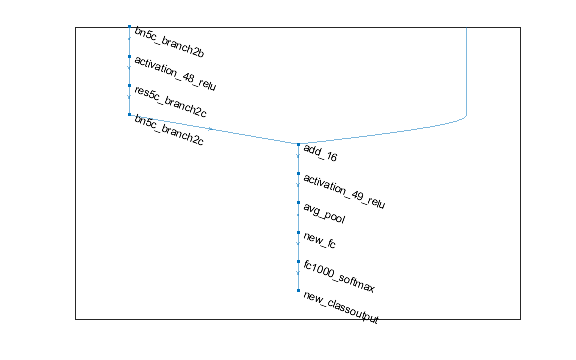

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

%pixelRange = [-30 30];
%scaleRange = [0.9 1.1];
%inputSize =[224 224 3];
%imageAugmenter = imageDataAugmenter( ...
 %   'RandXReflection',true, ...
 %   'RandXTranslation',pixelRange, ...
 %   'RandYTranslation',pixelRange, ...
  %  'RandXScale',scaleRange, ...
  %  'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain,'ColorPreprocessing','gray2rgb');

augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,'ColorPreprocessing','gray2rgb');

options = trainingOptions('adam', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',1, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Validation Images

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

Random Samples

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end